clear all;
close all;
clc;

% load data - Vel [m/s]; y [mm]
load('HotWireData_Baseline.mat')

my_y = y+yOffset %flip(y+yOffset);

my_y =     0.3667
    0.4667
    0.5667
    0.6667
    0.7667
    0.8667
    0.9667
    1.0667
    1.1667
    1.2667


idx1 = 50

idx1 = 50

idx2 = 51

idx2 = 51



my_Umean = flip(mean(Vel));
my_Ustd = flip(std(Vel));
my_Uskew = skewness(Vel);
my_Ukurt = kurtosis(Vel);

my_uprime = Vel - my_Umean;
S1 = my_uprime(:,idx1)

S1 =    -1.4290
   -1.4094
   -1.4278
   -1.4860
   -1.5283
   -1.5886
   -1.6382
   -1.6800
   -1.7032
   -1.7363


S2 = my_uprime(:,idx2)

S2 =    -5.1330
   -5.1829
   -5.2080
   -5.2113
   -5.1892
   -5.1803
   -5.1598
   -5.1451
   -5.0924
   -4.9880


[R,P] = corrcoef(S1,S2)

R =     1.0000    0.0409
    0.0409    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


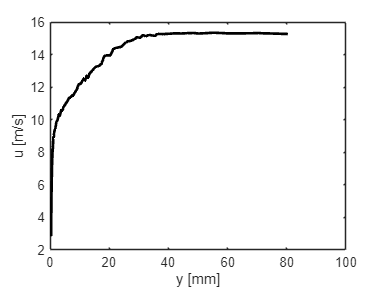


% plot
figure(1)
plot(my_y,my_Umean,'-k','LineWidth',2);
% hold on;
% plot(my_y,U,'.r');
xlabel('y [mm]')
ylabel('u [m/s]')

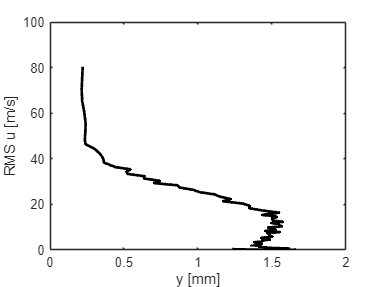


figure(2)
plot(my_Ustd,my_y,'-k','LineWidth',2);
% hold on;
% plot(my_y,flip(Urms),'.r');
xlabel('y [mm]')
ylabel('RMS u [m/s]')

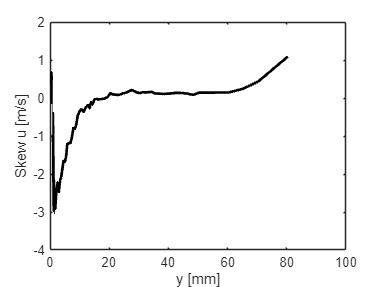


figure(3)
plot(my_y,my_Uskew,'-k','LineWidth',2);
% hold on;
% plot(my_y,flip(Urms),'.r');
xlabel('y [mm]')
ylabel('Skew u [m/s]')

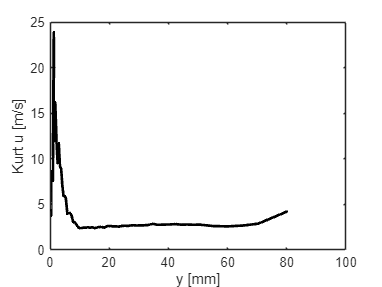


figure(4)
plot(my_y,my_Ukurt,'-k','LineWidth',2);
% hold on;
% plot(my_y,flip(Urms),'.r');
xlabel('y [mm]')
ylabel('Kurt u [m/s]')

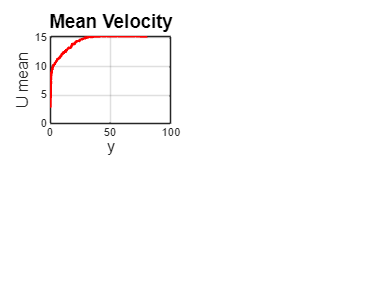

% Saving as publicatiion quaity images

figure;
tiledlayout(2, 2);  % Create a 2x2 tiled layout (2 rows and 2 columns)

% First plot (top-left)
nexttile;  % Move to the first tile
ax1 = plot(my_y, my_Umean, 'r-', 'LineWidth', 2);  % Plot sine wave in red
xlabel('y', 'FontSize', 12);  % x-axis label
ylabel('U mean', 'FontSize', 12);  % y-axis label
title('Mean Velocity', 'FontSize', 14);  % Plot title
grid on;  % Add grid


% Add annotation next to the first plot (proportional positioning)
annotation(ax1, [0.2, 0.75], 'String', 'This is the sine wave', ...
    'FontSize', 12, 'Color', 'r', 'FontWeight', 'bold');

Error using annotation (line 83)
First argument must be a valid annotation type or a handle to a figure, uipanel, or uitab.


% Second plot (top-right)
nexttile;  % Move to the second tile
plot(x, y2, 'b--', 'LineWidth', 2);  % Plot cosine wave in blue
xlabel('x', 'FontSize', 12);  % x-axis label
ylabel('cos(x)', 'FontSize', 12);  % y-axis label
title('Cosine Wave', 'FontSize', 14);  % Plot title
grid on;  % Add grid

% Add annotation next to the second plot
annotation('text', [0.8, 0.75], 'String', 'This is the cosine wave', ...
    'FontSize', 12, 'Color', 'b', 'FontWeight', 'bold');

% Third plot (bottom-left)
nexttile;  % Move to the third tile
plot(x, y3, 'g-.', 'LineWidth', 2);  % Plot tangent wave in green with dash-dot
xlabel('x', 'FontSize', 12);  % x-axis label
ylabel('tan(x)', 'FontSize', 12);  % y-axis label
title('Tangent Wave', 'FontSize', 14);  % Plot title
grid on;  % Add grid
axis([0, 2*pi, -10, 10]);  % Set axis limits for better visualization

% Add annotation next to the third plot
annotation('text', [0.2, 0.25], 'String', 'This is the tangent wave', ...
    'FontSize', 12, 'Color', 'g', 'FontWeight', 'bold');

% Fourth plot (bottom-right)
nexttile;  % Move to the fourth tile
plot(x, y4, 'm:', 'LineWidth', 2);  % Plot sine(2x) wave in magenta with dotted line
xlabel('x', 'FontSize', 12);  % x-axis label
ylabel('sin(2x)', 'FontSize', 12);  % y-axis label
title('Sine(2x) Wave', 'FontSize', 14);  % Plot title
grid on;  % Add grid

% Add annotation next to the fourth plot
annotation('text', [0.8, 0.25], 'String', 'This is the sine(2x) wave', ...
    'FontSize', 12, 'Color', 'm', 'FontWeight', 'bold');

% Adjust layout to avoid overlapping labels and title for the whole figure
sgtitle('Trigonometric Functions', 'FontSize', 16);  % Add a common title
R

% figure(99)
% plot(t,Vel(:,1))